Practice Problems 8 - Nonlinear Regression & Symbolic Toolbox

1) Fit a cubic polynomial to the following data by extending the system of equations on lecture slide 3, then calculate the standard error and correlation coefficient. Graph the data and your fitting equation.

x1 = [3, 4, 5, 7, 8, 9, 11, 12];
y1 = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6];
p1 = polyfit(x1, y1, 3);

% Calculate Standard Error
sr = 0;
st = 0;

% Perform Summation to find Sr and St
for m = 1:length(y1)
    sr = sr + (- x1(m)^3 * p1(1) - x1(m)^2 * p1(2) - x1(m) * p1(3) - p1(4) + y1(m))^2;
    st = st + (y1(m) - mean(y1))^2;
end

% Finding r2 (r2 = (st - sr)/st)
r2 = sqrt(1 - (sr/st))

r2 = 0.9105


% Finding synx (syx = sqrt(sr/(n- (m+1))))
synx = sqrt(sr/(length(y1) - (3 + 1)))

synx = 0.5700


% Try my function
syms x
eq = x^3 * p1(1) + x^2 * p1(2) + x * p1(3) + p1(4);
errorCorr(x1, y1, eq, 3)

ans =     0.5700    0.9105


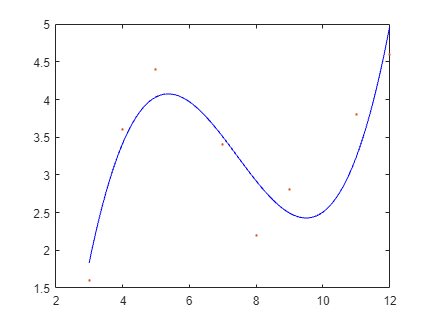


% Plot Graph

g1 = [3:0.1:12];
pp1 = polyval(p1, g1);
plot(g1, pp1, 'b')
hold on
plot(x1, y1, '.')
hold off

2) Do the same as in the Question 1 but using the general Z-matrix formulation given on slides 21-25. You should get the same result if you have done it correctly.

x2 = [3, 4, 5, 7, 8, 9, 11, 12]';
y2 = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6]';

z2 = [ones(size(x2)) x2 x2.^2 x2.^3];
a2 = (z2'*z2)\(z2'*y2)

a2 =   -11.4887
    7.1438
   -1.0412
    0.0467


3) Calculate the standard error for the 2 power equation models from Example 6 in the lecture notes and decide if one equation is better than the other or not.

% fNon = 2.5384 * x ^ 1.4359;
% fLin = 0.2741 * x ^ 1.9842;

% Data
x3 = [10:10:80]

x3 =     10    20    30    40    50    60    70    80


y3 = [25, 70, 380, 550, 610, 1220, 830, 1450]

y3 =           25          70         380         550         610        1220         830        1450


y3Lin = 0.2741 * x3 .^ 1.9842;
y3Non = 2.5384 * x3 .^ 1.4359;

% Summation to find sr
srLin = 0;
srNon = 0;
for m = 1:length(x3)
    srLin = srLin + (y3(m) - (0.2741 * x3(m) ^ 1.9842))^2;
    srNon = srNon + (y3(m) - (2.5384 * x3(m) ^ 1.4359))^2;
end

% Find Synx: syx = sqrt(sr/(n- (m+1)))
synx_linear = sqrt(srLin/(length(y3) - (1.9842 + 1)))

synx_linear = 262.5244

synx_nonlinear = sqrt(srNon/(length(y3) - (1.4359 + 1)))

synx_nonlinear = 200.0184


% Use My Equation
syms x
eq1 = 0.2741 * x ^ 1.9842;
eq2 = 2.5384 * x ^ 1.4359;

linear = errorCorr(x3, y3, eq1, 1.9842)

linear =   262.5244    0.8994


nonLinear = errorCorr(x3, y3, eq2, 1.9842)

nonLinear =   210.6674    0.9364


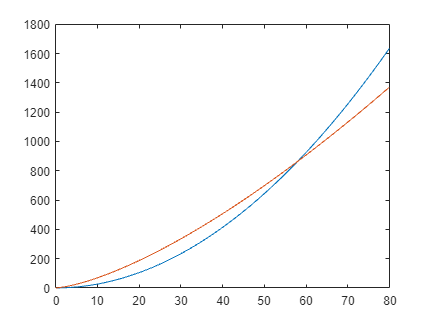


% Plot Graph
xP3 = [0:0.5:80];
y3LinG = 0.2741 * xP3 .^ 1.9842;
y3NonG = 2.5384 * xP3 .^ 1.4359;

plot(xP3, y3LinG, xP3, y3NonG);

4) For the following data use polynomial regression to get an equation that predicts the dissolved oxygen concentration as a function of temperature for the case where the chloride concentration is 0. Graph the data and your fitting equation.

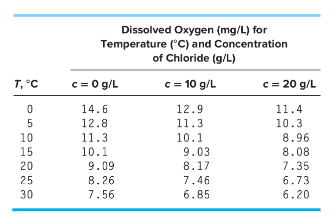

T4 = [0:5:30];
c4 = [14.6, 12.8, 11.3, 10.1, 9.09, 8.26, 7.56];
p42 = polyfit(T4, c4, 2)

p42 =     0.0044   -0.3634   14.5519


p43 = polyfit(T4, c4, 3)

p43 =    -0.0001    0.0073   -0.3956   14.6002



% See standard error for 2
syms x
eq1 = p42(1) * x^2 + p42(2) * x + p42(3);
errorCorr(T4, c4, eq1, 2)

ans =     0.0596    0.9998



% See standard error for 3
syms x
eq2 = p43(1) * x^3 + p43(2) * x^2 + p43(3) * x + p43(4);
errorCorr(T4, c4, eq2, 3)

ans =     0.0083    1.0000



%plot4 = [0:0.5:30];
%p4v = polyval(p42, plot4);
%plot(plot4, p4v);
%hold on
%plot(T4, c4, "o")
%hold off

5) For the data from Question 4 use multiple linear regression to predict the dissolved oxygen concentration as a function of temperature and chloride concentration (**Hint: Make a new table of values**). Plot the data and your equation then use your equation to predict the dissolved oxygen concentration when the chloride concentration is 15 g/L and temperature is 12oC

Oxygen estimated to be 9.4543 mg/L

T5val = [0:5:30];
T5 = [T5val T5val T5val]; % need 3 t5 val for x, y, and z for temperature
con = [0,0,0,0,0,0,0,10,10,10,10,10,10,10,20,20,20,20,20,20,20];
c05 = [14.6, 12.8, 11.3, 10.1, 9.09, 8.26, 7.56]; 
c105 = [12.9, 11.3, 10.1, 9.03, 8.17, 7.46, 6.85];
c205 = [11.4, 10.3, 8.96, 8.08, 7.35, 6.73, 6.20];
c = [c05 c105 c205];
coef = multipleLinearRegression(T5', con', c')

coef =    13.5221
   -0.2012
   -0.1049


% this is similar to giving the data x, y, and z coordinates where x is the
% temperature, y is the concentration and z is the dissolve oxygen

syms x1 x2
eq = coef(1) + coef(2) * x1 + coef(3) * x2;
double(subs(eq, {x1, x2}, {12, 15}))

ans = 9.5334

6) Use multiple linear regression to fit the following data. Also calculate the standard error and correlation coefficient.

x1 = [0 ,1, 1, 2, 2, 3, 3, 4, 4]

x1 =      0     1     1     2     2     3     3     4     4


x2 = [0, 1, 2, 1, 2, 1, 2, 1, 2]

x2 =      0     1     2     1     2     1     2     1     2


y = [15.1, 17.9, 12.7, 25.6, 20.5, 35.1, 29.7, 45.4, 40.2]

y =    15.1000   17.9000   12.7000   25.6000   20.5000   35.1000   29.7000   45.4000   40.2000



% use multiplelinearregression function
coefficients = multipleLinearRegression(x1', x2', y')

coefficients =    14.4609
    9.0252
   -5.7043



newx1 = coefficients(2) * x1

newx1 =          0    9.0252    9.0252   18.0504   18.0504   27.0757   27.0757   36.1009   36.1009


newx2 = coefficients(3) * x2

newx2 =          0   -5.7043  -11.4087   -5.7043  -11.4087   -5.7043  -11.4087   -5.7043  -11.4087


newy = coefficients(1) + newx1 + newx2

newy =    14.4609   17.7817   12.0774   26.8070   21.1026   35.8322   30.1278   44.8574   39.1530


7) Fluid flow was measured in concrete circular pipes of various sizes and angles (slopes). Use multiple linear regression (logarithm method) to fit the following equation to the data.

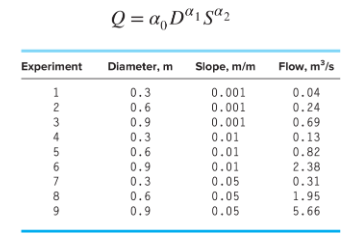

% Data
experiment = [1:1:9];
d = [0.3, 0.6, 0.9, 0.3, 0.6, 0.9, 0.3, 0.6, 0.9];
s = [0.001, 0.001, 0.001, 0.01, 0.01, 0.01, 0.05, 0.05, 0.05];
q = [0.04, 0.24, 0.69, 0.13, 0.82, 2.38, 0.31, 1.95, 5.66];


% linearize equation Q = a0 * d^a1 * s^a2 by taking log both side
% you will get logQ = log(a0) + a1log(d) + a2log(s)

% Find log(d), log(s), log(Q)
logd = log(d);
logs = log(s);
logq = log(q);
a = multipleLinearRegression(logd', logs', logq');

% we get logQ = log(a0) + a1log(d) + a2log(s)
% since log(a0) = 3.5941, solve to find a0 by exp(3.5941)
a1final = exp(a(1));

% display answer
disp(a1final);

   36.3813



disp(a(2));

    2.6279



disp(a(3));

    0.5320



8. Three disease-carrying organisms decay exponentially in seawater according to the following model equation. Use general least squares to estimate the coefficients and estimate the initial concentration of each organism from the following measurements.

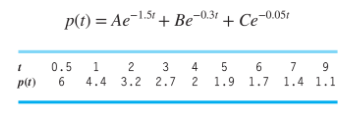

% Datas
t = [0.5, 1, 2, 3, 4, 5, 6 ,7 ,9]'

t =     0.5000
    1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000
    9.0000


y = [6, 4.4, 3.2, 2.7, 2, 1.9, 1.7, 1.4, 1.1]'

y =     6.0000
    4.4000
    3.2000
    2.7000
    2.0000
    1.9000
    1.7000
    1.4000
    1.1000



% zeros(size(t)) is to fill a column with 0 since there is no D where De^t
% exist, if exist then it should be 1
% exp(-1.5.*t) is adding e^(-1.5t) etc...
z = [zeros(size(t)) exp(-1.5.*t) exp(-0.3.*t) exp(-0.05.*t)]

z =          0    0.4724    0.8607    0.9753
         0    0.2231    0.7408    0.9512
         0    0.0498    0.5488    0.9048
         0    0.0111    0.4066    0.8607
         0    0.0025    0.3012    0.8187
         0    0.0006    0.2231    0.7788
         0    0.0001    0.1653    0.7408
         0    0.0000    0.1225    0.7047
         0    0.0000    0.0672    0.6376


a = (z'*z)\(z'*y)

a =        NaN
    4.1375
    2.8959
    1.5349


Function

function err = errorCorr(a, b, eq, no)
% for calculating any polynomials EXCEPT multivariable polynomials
% a is array x, b is array y, eq is syms with var x , y, no is no. of
% polynomials
    
    sr = 0;
    st = 0;

    for m = 1:length(a)
        A = a(m);
        syms x
        sr = sr + (b(m) - (subs(eq, x, A)))^2;
        st = st + (b(m) - mean(b))^2;
    end

    % Finding r2 (r2 = (st - sr)/st)
    r2 = sqrt(1 - (sr/st));

    % Finding synx (syx = sqrt(sr/(n- (m+1))))
    synx = sqrt(sr/(length(b) - (no + 1)));

    % Return both synx, r2
    err = [double(synx), double(r2)];
end

% tval = 0:5:30;
% t = [tval tval tval]';
% c = [0 0 0 0 0 0 0 10 10 10 10 10 10 10 20 20 20 20 20 20 20]';
% y = [14.6 12.8 11.3 10.1 9.09 8.26 7.56 12.9 11.3 10.1 9.03 8.17 7.46 6.85 11.4 10.3 8.96 8.08 7.35 6.73 6.20]';

%  Step 2: Solve for a to create fitted function
% z = [ones(size(t)) t c];  % เป็น 2 ตัวแปร
% a = (z'*z)\(z'*y);

%  Step 3: Create fitted function
% fitted_func = @(temp, concent) a(1) + a(2).*temp + a(3).*concent;

%  Step 4: Eval the value
% fprintf('Oxygen estimated to be %f\n', fitted_func(12, 15));

function [coefficients] = multipleLinearRegression(x, y, z)
% remember to flip x, y, and z
    a = [ones(size(x)) x y]; % create matrix of 1s size x
    b = (a'*a)\(a'*z); % find coefficient
    coefficients = b;
end